## 实现点到曲面距离的计算

本脚本主要为了实现点到曲面距离的计算。

## 第一部分：利用定义计算点到解析曲面f(x,y,z)的距离

EPS = 1e-6;

% point
% Px = '5';
% Py = 5;
% Pz = 100;
Px = 3.7;
Py = 5;
Pz = 109.4;
P = [Px,Py,Pz];

% surface function
func = @(x,y) x.^2 + y.^2;
syms x y;
func_x = matlabFunction(diff(func,x),'Vars',{x,y});
func_y = matlabFunction(diff(func,y),'Vars',{x,y});

% solve the non-linear eqs
Q = fsolve(@(Q) eqs2solve(Q,P,func),P(1:2));


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Q(3) = func(Q(1),Q(2));

点P到曲面的距离为：

dist = norm(P - Q)

dist = 4.2345

% plot the result
[ptsMeshX,ptsMeshY] = meshgrid(linspace(-10,10),linspace(-10,10));
ptsMeshZ = func(ptsMeshX,ptsMeshY);

% figure;
% surf(ptsMeshX,ptsMeshY,ptsMeshZ,'FaceAlpha',0.3,'EdgeColor','none');
% hold on;
% scatter3(P(1),P(2),P(3));
% scatter3(Q(1),Q(2),Q(3));
% quiver3(Q(1),Q(2),Q(3),func_x(Q(1),Q(2)),func_y(Q(1),Q(2)),-1);
% line([P(1),Q(1)],[P(2),Q(2)],[P(3),Q(3)]);
% xlabel('x'); 
% ylabel('y'); 
% zlabel('z');

Qx = Q(1);
Qy = Q(2);
Qz = Q(3);
Lx = [P(1),Q(1)];
Ly = [P(2),Q(2)];
Lz = [P(3),Q(3)];
Quivx = func_x(Q(1),Q(2));
Quivy = func_y(Q(1),Q(2));
Quivz = -1;

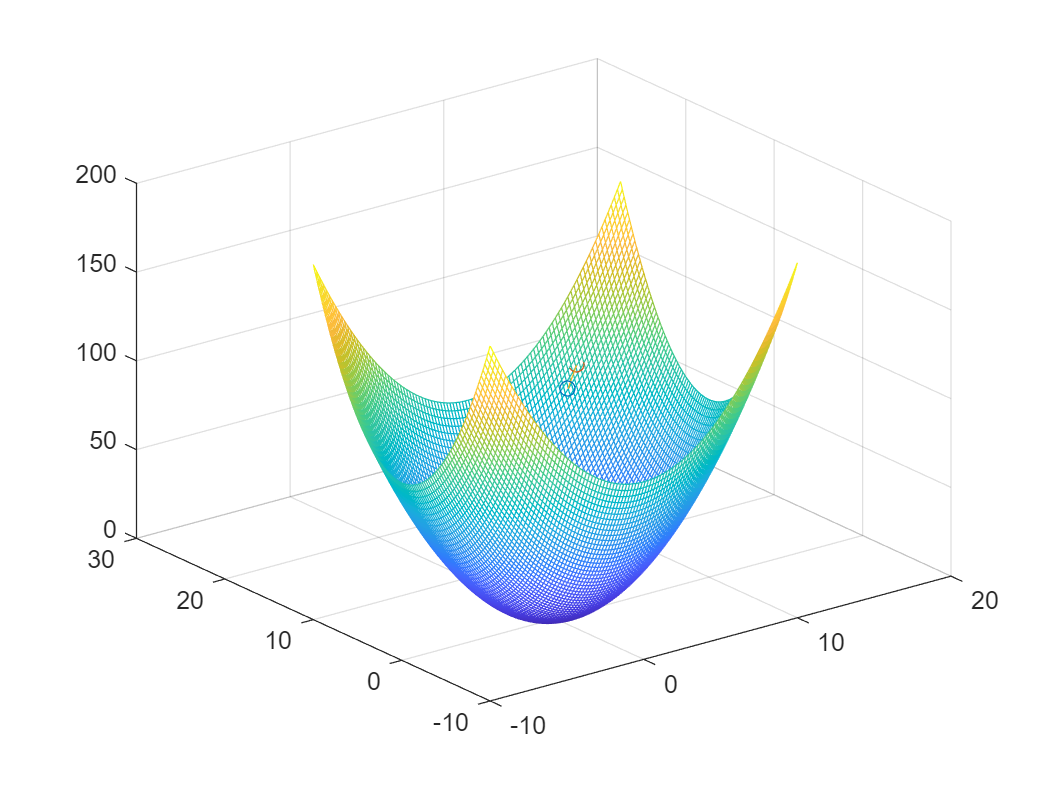

figure
% Create mesh of ptsMeshX, ptsMeshY, and ptsMeshZ
mesh(ptsMeshX,ptsMeshY,ptsMeshZ);

hold on
% Create scatter3 of Px, Py, and Pz
scatter3(Px,Py,Pz,"DisplayName","Pz");
% Create scatter3 of Qx, Qy, and Qz
scatter3(Qx,Qy,Qz,"DisplayName","Qz");
% Create plot3 of Lx, Ly, and Lz
plot3(Lx,Ly,Lz,"DisplayName","Lz");
% Create quiver3 of Qx, Qy, and Qz
quiver3(Qx,Qy,Qz,Quivx,Quivy,Quivz);
hold off

上述方法是有局限性的，当点到曲面距离较远的时候并不适用。例如，取P点为[5,5,200]得到的结果就不对了。

function F = eqs2solve(Q,P,func)
syms x y;
func_x = matlabFunction(diff(func,x),'Vars',{x,y});
func_y = matlabFunction(diff(func,y),'Vars',{x,y});
F(1) = (P(1) - Q(1)) + func_x(Q(1),Q(2)) .* (P(3) - func(Q(1),Q(2)));
F(2) = (P(2) - Q(2)) + func_y(Q(1),Q(2)) .* (P(3) - func(Q(1),Q(2)));
end